### Exercise 1.2.

*(i) Solve the system of linear equations*

      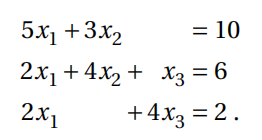

*by rearranging the equation and using the command *`linsolve()`*. *

*Analyze if and how many solutions exist*

### Answer

#### *Initialization*

[`X`](https://ww2.mathworks.cn/help/symbolic/linsolve.html?searchHighlight=linsolve&s_tid=srchtitle_linsolve_2#btezcvj-X) `=` `linsolve``(`[`A`](https://ww2.mathworks.cn/help/symbolic/linsolve.html?searchHighlight=linsolve&s_tid=srchtitle_linsolve_2#btezcvj-A)`,`[`B`](https://ww2.mathworks.cn/help/symbolic/linsolve.html?searchHighlight=linsolve&s_tid=srchtitle_linsolve_2#btezcvj-B)`)` solves the matrix equation `A``X`` = ``B`, where `B` is a column vector.

Therefore one has to rewrite this system of linear equations in matrix form.

clc;
clear;

% a command to surpress simplifies output, can be toggled
sympref('AbbreviateOutput', false);

% rewrite the equations in matrix form
A = [5,3,0; 2,4,1; 2,0,4]

A =      5     3     0
     2     4     1
     2     0     4


B = [10;6;2]

B =     10
     6
     2


#### *Solve the matrix equation*

X = linsolve(A,B)

X =     1.5161
    0.8065
   -0.2581


#### *Analysis*

For linear matrix equations, one necessary and sufficient condition of the existence of solutions is that the ranks of the coefficient matrix `A` and its augmented matrix `[``A,B``]` are equal, which are both 3 in this case. Thus, it is guaranteed that solutions exist.

Plus, the rank of matrix `A` is equivalent to the dimension of matrix `X`. Therefore, the number of solutions is supposed to be 1.

*(ii) Represent the system as a set of linear symbolic equations by creating the symbols *`x``1,``x``2,``x``3` *and solve the system using *`solve()`*. Compare the solutions.*

### Answer

% Create symbols and equations
syms x1 x2 x3
eqn1 = 5*x1 + 3*x2 == 10

$$eqn1 = 5\,x_{1}+3\,x_{2}=10$$

eqn2 = 2*x1 + 4*x2 + x3 == 6

$$eqn2 = 2\,x_{1}+4\,x_{2}+x_{3}=6$$

eqn3 = 2*x1 + 4*x3 == 2

$$eqn3 = 2\,x_{1}+4\,x_{3}=2$$


% Solve the equation set
sol = solve([eqn1, eqn2, eqn3], [x1, x2, x3])

sol = 包含以下字段的 struct :
    x1: 47/31
    x2: 25/31
    x3: -8/31



% Calculate values to 5 significant digits
vpa([sol.x1,sol.x2,sol.x3],5)

$$ans = \left(\begin{array}{ccc} 1.5161 & 0.80645 & -0.25806 \end{array}\right)$$

#### *Analysis*

From the result it can be concluded that both methods in the last two subsections are correct and got the same answers. 

### Exercise 1.3.

*(i) How many solutions has the system of linear equations*

  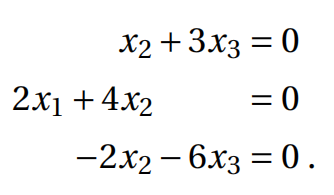

*Write a short explanation.*

*(ii) Try to calculate the solution using *`linsolve()`*.*

### **Answer**

For simplicity of illustration, we run the codes first.

% rewrite the equations in matrix form
A1 = [0,1,3; 2,4,0; 0,-2,-6]

A1 =      0     1     3
     2     4     0
     0    -2    -6


B1 = [0;0;0]

B1 =      0
     0
     0



X1 = linsolve(A1,B1)

X1 =    NaN
   NaN
   NaN


A warning is shown as: Solution is not unique because the system is rank-deficient. And apparently  `linsolve()` cannot get a reasonable answer.

#### *Analysis*

This is because although the ranks of the `A1` and its augmented matrix` [``A1,B1``] `are equal, which implies solutions exist, the rank of matrix `A1` is 2, which is less than the dimension of `X1` 3.

### Exercise 1.4.

*(i) Solve the equation*

 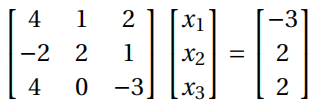

### **Answer**

A2 = [4,1,2; -2,2,1; 4,0,-3]

A2 =      4     1     2
    -2     2     1
     4     0    -3


B2 = [-3;2;2]

B2 =     -3
     2
     2



X2 = linsolve(A2,B2)

X2 =    -0.4286
    1.1905
   -1.2381


*(ii) **Transfer the matrix equation into a system of linear equations and solve it by the use of its inverse. Matlab offers the functionality of the backslash-operator "\". Look up, what this operator does and use it to solve the equation. Write a short comment on that in your fifile. *

### Answer

% Convert the matrix equation into a system of linear equations
eqn_a = 4*x1 + 1*x2 + 2*x3 == -3

$$eqn\_a = 4\,x_{1}+x_{2}+2\,x_{3}=-3$$

eqn_b = -2*x1 + 2*x2 + x3 == 2

$$eqn\_b = 2\,x_{2}-2\,x_{1}+x_{3}=2$$

eqn_c = 4*x1 - 3*x3 == 2

$$eqn\_c = 4\,x_{1}-3\,x_{3}=2$$


sol2 = solve([eqn_a, eqn_b, eqn_c], [x1, x2, x3])

sol2 = 包含以下字段的 struct :
    x1: -3/7
    x2: 25/21
    x3: -26/21


vpa([sol2.x1,sol2.x2,sol2.x3],5) % Calculate values to 5 significant digits

$$ans = \left(\begin{array}{ccc} -0.42857 & 1.1905 & -1.2381 \end{array}\right)$$


tic
% Calculate matrix X2: [x1;x2;x3]
X2_new = inv(A2) * B2

X2_new =    -0.4286
    1.1905
   -1.2381


toc

历时 0.004914 秒。


tic
% Check the function of backslash-operator "\"
A2\B2

ans =    -0.4286
    1.1905
   -1.2381


toc

历时 0.004468 秒。


#### *Analysis*

The answers are the same. So it can be inferred that backslash-operator solves the system of linear equations `A2*X2 = B2`. 

If we however measure the time taken for each approach, it can be seen that the backslash operator is faster than the basic process of getting the inverse of `A2` first and then multiply its inverse with `B2`.

### Exercise 1.5.

Consider the ordinary differential equation

with the arbitrary but constant inhomogeneity `γ` and constant parameter `α ∈ ``(0, 1)`.

*(i) Construct the differential equation *(1.4) *as a symbolic equation. *

### Answer

% using diff(function, variable) to describe differentiations
syms y(t) % Create a time-dependant symbol
syms alpha gamma
dy = diff(y,t)

$$dy(t) = \frac{\partial }{\partial t}y\left(t\right)$$

ode = 0.5* diff(y,t,2)+ 2* alpha* dy + 4* y == gamma % ode is an equation: dx/dt -x =0

$$ode(t) = \frac{\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)}{2}+2\,\alpha \,\frac{\partial }{\partial t}y\left(t\right)+4\,y\left(t\right)=\gamma$$

*(ii) **Solve the differential equation *(1.4) *by using *`dsolve()`*. Comment on the stability of the system based on the zeros of the characteristic polynomial.*

### Answer

dsolve(ode) % solve a differetial equation

$$ans = \frac{\gamma }{4}+C_{1}\,{\mathrm{e}}^{-t\,\left(2\,\alpha +2\,\sqrt{\alpha^{2}-2}\right)}+C_{2}\,{\mathrm{e}}^{-t\,\left(2\,\alpha -2\,\sqrt{\alpha^{2}-2}\right)}$$

#### *Analysis*

Observing from the solution, one zero is great than zero and the other is negative. So the system is instable.

 *(iii) **Introduce suitable state variables and transfer the differential equation (1.4) into state space representation with input *`γ` *and output *`y``(``t``)`*. Using the eigenvalues of the system matrix, analyze the stability of the system. Calculate the general solution of the system, e.g., using the solution formula for linear, time-invariant systems (see script for the lecture Control Systems [1], Theorem 3.1). *

### Answer

Make `x1(t) = y(t)` and `x2(t) = dy(t)/dt`, in this way we can write this system in state space representation as below:

A = [0 1; -8 -4*alpha]

$$A = \left(\begin{array}{cc} 0 & 1\\ -8 & -4\,\alpha \end{array}\right)$$

B = [0; 2]

B =      0
     2


C = [1 0]

C =      1     0


D = 0

D = 0


eigVls = eig(A) 

$$eigVls = \left(\begin{array}{c} -2\,\alpha -2\,\sqrt{\alpha^{2}-2}\\ 2\,\sqrt{\alpha^{2}-2}-2\,\alpha \end{array}\right)$$


syms phi(t)
phi = exp(A*t)

$$phi = \left(\begin{array}{cc} 1 & {\mathrm{e}}^{t}\\ {\mathrm{e}}^{-8\,t} & {\mathrm{e}}^{-4\,\alpha \,t} \end{array}\right)$$


syms x10 x20 X_new tau

expr = expm(A*(t-tau))*B*gamma

$$expr = \left(\begin{array}{c} \frac{\gamma \,\left({\mathrm{e}}^{2\,\alpha \,\tau -2\,\alpha \,t-2\,t\,\sqrt{\alpha^{2}-2}+2\,\tau \,\sqrt{\alpha^{2}-2}}\,\left(\alpha^{2}-2\right)-{\mathrm{e}}^{2\,\alpha \,\tau -2\,\alpha \,t+2\,t\,\sqrt{\alpha^{2}-2}-2\,\tau \,\sqrt{\alpha^{2}-2}}\,\left(\alpha^{2}-2\right)-\alpha^{2}\,{\mathrm{e}}^{2\,\alpha \,\tau -2\,\alpha \,t-2\,t\,\sqrt{\alpha^{2}-2}+2\,\tau \,\sqrt{\alpha^{2}-2}}+\alpha^{2}\,{\mathrm{e}}^{2\,\alpha \,\tau -2\,\alpha \,t+2\,t\,\sqrt{\alpha^{2}-2}-2\,\tau \,\sqrt{\alpha^{2}-2}}\right)}{4\,\sqrt{\alpha^{2}-2}}\\ \frac{\gamma \,\left(\alpha \,{\mathrm{e}}^{2\,\alpha \,\tau -2\,\alpha \,t-2\,t\,\sqrt{\alpha^{2}-2}+2\,\tau \,\sqrt{\alpha^{2}-2}}-\alpha \,{\mathrm{e}}^{2\,\alpha \,\tau -2\,\alpha \,t+2\,t\,\sqrt{\alpha^{2}-2}-2\,\tau \,\sqrt{\alpha^{2}-2}}+{\mathrm{e}}^{2\,\alpha \,\tau -2\,\alpha \,t-2\,t\,\sqrt{\alpha^{2}-2}+2\,\tau \,\sqrt{\alpha^{2}-2}}\,\sqrt{\alpha^{2}-2}+{\mathrm{e}}^{2\,\alpha \,\tau -2\,\alpha \,t+2\,t\,\sqrt{\alpha^{2}-2}-2\,\tau \,\sqrt{\alpha^{2}-2}}\,\sqrt{\alpha^{2}-2}\right)}{\sqrt{\alpha^{2}-2}} \end{array}\right)$$

X_new = int(expr,tau,[0,t]) + phi* [x10; x20]

$$X\_new = \left(\begin{array}{c} \frac{\gamma }{4}+x_{10}+x_{20}\,{\mathrm{e}}^{t}-\frac{\gamma \,{\mathrm{e}}^{-2\,\alpha \,t}\,{\mathrm{e}}^{-2\,t\,\sqrt{\alpha^{2}-2}}}{8}-\frac{\gamma \,{\mathrm{e}}^{-2\,\alpha \,t}\,{\mathrm{e}}^{2\,t\,\sqrt{\alpha^{2}-2}}}{8}+\frac{\alpha \,\gamma \,{\mathrm{e}}^{-2\,\alpha \,t}\,{\mathrm{e}}^{-2\,t\,\sqrt{\alpha^{2}-2}}}{8\,\sqrt{\alpha^{2}-2}}-\frac{\alpha \,\gamma \,{\mathrm{e}}^{-2\,\alpha \,t}\,{\mathrm{e}}^{2\,t\,\sqrt{\alpha^{2}-2}}}{8\,\sqrt{\alpha^{2}-2}}\\ x_{10}\,{\mathrm{e}}^{-8\,t}+x_{20}\,{\mathrm{e}}^{-4\,\alpha \,t}-\frac{\gamma \,{\mathrm{e}}^{-2\,\alpha \,t}\,{\mathrm{e}}^{-2\,t\,\sqrt{\alpha^{2}-2}}-\gamma \,{\mathrm{e}}^{-2\,\alpha \,t}\,{\mathrm{e}}^{2\,t\,\sqrt{\alpha^{2}-2}}}{2\,\sqrt{\alpha^{2}-2}} \end{array}\right)$$

Y = C*X_new + D*gamma

$$Y = \frac{\gamma }{4}+x_{10}+x_{20}\,{\mathrm{e}}^{t}-\frac{\gamma \,{\mathrm{e}}^{-2\,\alpha \,t}\,{\mathrm{e}}^{-2\,t\,\sqrt{\alpha^{2}-2}}}{8}-\frac{\gamma \,{\mathrm{e}}^{-2\,\alpha \,t}\,{\mathrm{e}}^{2\,t\,\sqrt{\alpha^{2}-2}}}{8}+\frac{\alpha \,\gamma \,{\mathrm{e}}^{-2\,\alpha \,t}\,{\mathrm{e}}^{-2\,t\,\sqrt{\alpha^{2}-2}}}{8\,\sqrt{\alpha^{2}-2}}-\frac{\alpha \,\gamma \,{\mathrm{e}}^{-2\,\alpha \,t}\,{\mathrm{e}}^{2\,t\,\sqrt{\alpha^{2}-2}}}{8\,\sqrt{\alpha^{2}-2}}$$

#### *Analysis*

When using dsovle, the initial condition was set to be 0. This is the reason there is a difference between the results of the last two methods.

*(iv) Determine the numerical solution for the parameter values *`α=``4/7``, γ=−``0.8` *and the initial conditions *`y``(0)``=``1``, y``˙(0)``=``1`*. Plot the solution trajectory *`t→``[``y``(``t``),``y``˙(``t``),``t``]` *for times *`t∈``[0,25]`*. *

### **Answer**

% initial conditions y(0) = 1 and ydot(0) = 1
y0 = y(0) == 1;
dot_y0 = dy(0) == 1;
% replacing the values of alpha and gamma 
ode = subs( ode, {alpha gamma}, {4/7 -0.8});
% solving the differential equation using dsolve()
ySol(t) = dsolve( ode, [y0, dot_y0])

$$ySol(t) = \frac{6\,{\mathrm{e}}^{-\frac{8\,t}{7}}\,\cos\left(\frac{2\,\sqrt{82}\,t}{7}\right)}{5}+\frac{83\,\sqrt{82}\,{\mathrm{e}}^{-\frac{8\,t}{7}}\,\sin\left(\frac{2\,\sqrt{82}\,t}{7}\right)}{820}-\frac{1}{5}$$

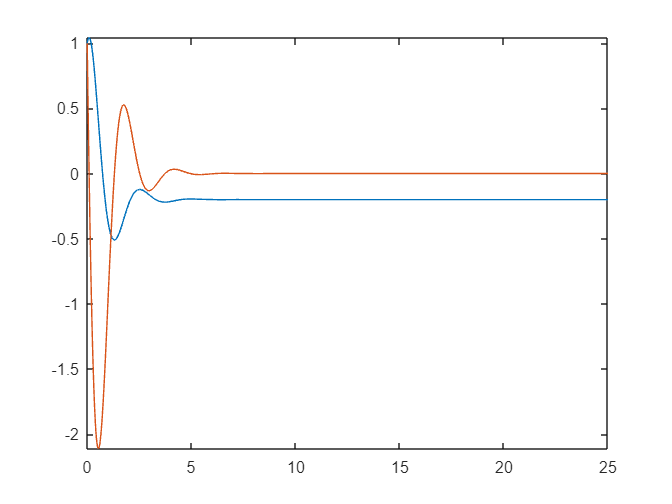

% plot
fplot(t,ySol,[0,25])
hold on
fplot(t,diff(ySol),[0,25])
hold off

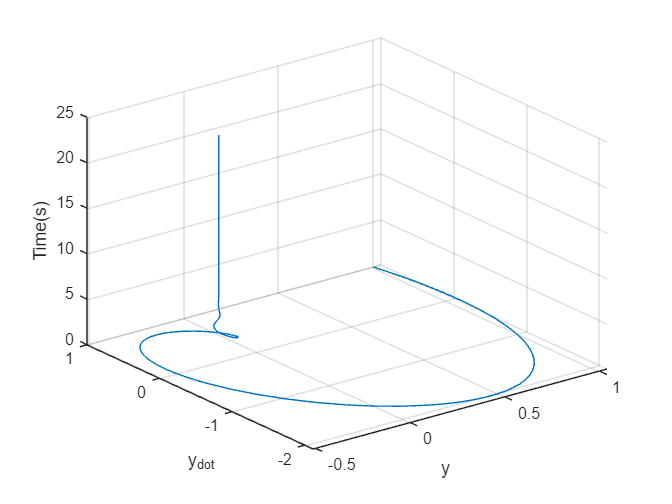

% 3D-plot
fplot3(ySol, diff(ySol), t, [0,25])
xlabel('y')
ylabel('y_{dot}')
zlabel('Time(s)')


% self-check
double(subs(ySol,t,10))

ans = -0.2000

According to the answer, `t(10)= -0.2`.

### Exercise 1.6.

*Transform the function into the laplace domain*


$$f(t) = cos(3wt) + t^3e^{-at}$$


syms w a t
f1 = cos(3*w*t) + ((t^3)*exp(-a*t))

$$f1 = \cos\left(3\,t\,w\right)+t^{3}\,{\mathrm{e}}^{-a\,t}$$

F1 = laplace(f1)

$$F1 = \frac{6}{{\left(a+s\right)}^{4}}+\frac{s}{s^{2}+9\,w^{2}}$$

*Transform the function into the laplace domain*


$$\hat{f}(s) = \frac{w}{(s+a)^2 + w^4} + \frac{7}{s}$$


syms w a s
F2 = (w/(((s+a)^2)+(w^4))) + (7/s)

$$F2 = \frac{7}{s}+\frac{w}{{\left(a+s\right)}^{2}+w^{4}}$$

f2 = ilaplace(F2)

$$f2 = \frac{\sin\left(t\,w^{2}\right)\,{\mathrm{e}}^{-a\,t}}{w}+7$$

### **Exercise 1.8.**

*(i) Determine suitable generalized coordinates *`q` *for the double pendulum. *

### Answer

Here we concentrate only on the pendulum arms. In this way, 3 generalized coordinates are defined as the degrees of freedom of the pendulum system is 2 and its origin has 1 degree of freedom.

% clean up
clc;
clear;

% stop matlab from using simplifications in the output; 
% toggle if desired
sympref('AbbreviateOutput', false) ;

#### **Generalized coordinates**

% define the symbols as function of time
syms phi1(t) phi2(t)  % Angular position of the pendulum arms
syms y0  % Displacement of the carriage

% define 2 generalized coordinates
q = [ phi1(t); phi2(t)] 

$$q = \left(\begin{array}{c} \varphi_{1}\left(t\right)\\ \varphi_{2}\left(t\right) \end{array}\right)$$

q_dot = diff(q,t)

$$q\_dot = \left(\begin{array}{c} \frac{\partial }{\partial t}\varphi_{1}\left(t\right)\\ \frac{\partial }{\partial t}\varphi_{2}\left(t\right) \end{array}\right)$$

*(ii) Set up the equations of motion of the double pendulum using the Lagrange formalism. *

### Answer

At the first place, it is needed to define rotation and displacement matrixes, which are necessary for the Lagrange formalism. 

#### **Coordinate transformation **

The double pendulum is rotated around the `x`-axis by the angle `phixi`.

The matrix `R10` describes the angular transformation from Pendulum arm `1 `to the carriage. Similarly, `R21` describes the angular transformation from Pendulum arm 2` to` Pendulum arm 1.

R10 = [ 1       0               0;
        0       cos(phi1(t))    -sin(phi1(t));
        0       sin(phi1(t))    cos(phi1(t));   ]

$$R10 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\varphi_{1}\left(t\right)\right) & -\sin\left(\varphi_{1}\left(t\right)\right)\\ 0 & \sin\left(\varphi_{1}\left(t\right)\right) & \cos\left(\varphi_{1}\left(t\right)\right) \end{array}\right)$$

    
R21 = [ 1       0               0;
    0       cos(phi2(t)-phi1(t))    -sin(phi2(t)-phi1(t));
    0       sin(phi2(t)-phi1(t))    cos(phi2(t)-phi1(t));   ]

$$R21 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\varphi_{1}\left(t\right)-\varphi_{2}\left(t\right)\right) & \sin\left(\varphi_{1}\left(t\right)-\varphi_{2}\left(t\right)\right)\\ 0 & -\sin\left(\varphi_{1}\left(t\right)-\varphi_{2}\left(t\right)\right) & \cos\left(\varphi_{1}\left(t\right)-\varphi_{2}\left(t\right)\right) \end{array}\right)$$


R0i = eye(3)

R0i =      1     0     0
     0     1     0
     0     0     1



% back transformations
R01 = transpose(R10)

$$R01 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\varphi_{1}\left(t\right)\right) & \sin\left(\varphi_{1}\left(t\right)\right)\\ 0 & -\sin\left(\varphi_{1}\left(t\right)\right) & \cos\left(\varphi_{1}\left(t\right)\right) \end{array}\right)$$

R12 = transpose(R21)

$$R12 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\varphi_{1}\left(t\right)-\varphi_{2}\left(t\right)\right) & -\sin\left(\varphi_{1}\left(t\right)-\varphi_{2}\left(t\right)\right)\\ 0 & \sin\left(\varphi_{1}\left(t\right)-\varphi_{2}\left(t\right)\right) & \cos\left(\varphi_{1}\left(t\right)-\varphi_{2}\left(t\right)\right) \end{array}\right)$$

#### Shift of the origin of coordinates

Then it comes to the translation part. `dxy` specifies that it is the coordinates of the origin of system `x` expressed in coordinate notation of the system `y`.

syms l1 l_s1 m_G1 J_G1xx

d10 = [ 0;
        0;
        0; ]

d10 =      0
     0
     0



syms l2 l_s2 m_G2 J_G2xx

d21 = [ 0;
        0;
        l1;]

$$d21 = \left(\begin{array}{c} 0\\ 0\\ l_{1} \end{array}\right)$$


% here d0i specifies the translation matrix from the carriage to inertial system
d0i = [ 0;
        y0;
        0;]

$$d0i = \left(\begin{array}{c} 0\\ y_{0}\\ 0 \end{array}\right)$$

#### Center of mass

Center of mass of the two pendulum arms.

sG1_1 = [0; 0; l_s1];
sG2_2 = [0; 0; l_s2];

sG1_0 = d10 + R10*sG1_1

$$sG1\_0 = \left(\begin{array}{c} 0\\ -l_{\mathrm{s1}}\,\sin\left(\varphi_{1}\left(t\right)\right)\\ l_{\mathrm{s1}}\,\cos\left(\varphi_{1}\left(t\right)\right) \end{array}\right)$$

sG2_0 = d10 + R10*(d21 + R21*sG2_2);
sG2_0 = simplify(sG2_0)

$$sG2\_0 = \left(\begin{array}{c} 0\\ -l_{1}\,\sin\left(\varphi_{1}\left(t\right)\right)-l_{\mathrm{s2}}\,\sin\left(\varphi_{2}\left(t\right)\right)\\ l_{1}\,\cos\left(\varphi_{1}\left(t\right)\right)+l_{\mathrm{s2}}\,\cos\left(\varphi_{2}\left(t\right)\right) \end{array}\right)$$


sG1_i = d0i + sG1_0

$$sG1\_i = \left(\begin{array}{c} 0\\ y_{0}-l_{\mathrm{s1}}\,\sin\left(\varphi_{1}\left(t\right)\right)\\ l_{\mathrm{s1}}\,\cos\left(\varphi_{1}\left(t\right)\right) \end{array}\right)$$

sG2_i = d0i + sG2_0

$$sG2\_i = \left(\begin{array}{c} 0\\ y_{0}-l_{1}\,\sin\left(\varphi_{1}\left(t\right)\right)-l_{\mathrm{s2}}\,\sin\left(\varphi_{2}\left(t\right)\right)\\ l_{1}\,\cos\left(\varphi_{1}\left(t\right)\right)+l_{\mathrm{s2}}\,\cos\left(\varphi_{2}\left(t\right)\right) \end{array}\right)$$

#### Velocities and angular velocities in generalized coordinates

% method 1
v_G1 = diff(sG1_i, t)

$$v\_G1 = \left(\begin{array}{c} 0\\ -l_{\mathrm{s1}}\,\cos\left(\varphi_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\varphi_{1}\left(t\right)\\ -l_{\mathrm{s1}}\,\sin\left(\varphi_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\varphi_{1}\left(t\right) \end{array}\right)$$

v_G2 = diff(sG2_i, t)

$$v\_G2 = \left(\begin{array}{c} 0\\ -l_{1}\,\cos\left(\varphi_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\varphi_{1}\left(t\right)-l_{\mathrm{s2}}\,\cos\left(\varphi_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\varphi_{2}\left(t\right)\\ -l_{1}\,\sin\left(\varphi_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\varphi_{1}\left(t\right)-l_{\mathrm{s2}}\,\sin\left(\varphi_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\varphi_{2}\left(t\right) \end{array}\right)$$

% method 2
v_G1 = jacobian(sG1_i, q)*q_dot

$$v\_G1 = \left(\begin{array}{c} 0\\ -l_{\mathrm{s1}}\,\cos\left(\varphi_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\varphi_{1}\left(t\right)\\ -l_{\mathrm{s1}}\,\sin\left(\varphi_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\varphi_{1}\left(t\right) \end{array}\right)$$

v_G2  = jacobian(sG2_i, q)*q_dot

$$v\_G2 = \left(\begin{array}{c} 0\\ -l_{1}\,\cos\left(\varphi_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\varphi_{1}\left(t\right)-l_{\mathrm{s2}}\,\cos\left(\varphi_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\varphi_{2}\left(t\right)\\ -l_{1}\,\sin\left(\varphi_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\varphi_{1}\left(t\right)-l_{\mathrm{s2}}\,\sin\left(\varphi_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\varphi_{2}\left(t\right) \end{array}\right)$$


% Skew-symmetric matrices with helper function SRx1() (at EOF)
S0 = arrayfun(@(x) SRxx(x,R0i,t), q, "UniformOutput", 0);
S0x = simplify(S0{1}+S0{2})

$$S0x = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

omegaG0_i = [S0x(3,2); S0x(1,3); S0x(2,1)]

$$omegaG0\_i = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$


S1 = arrayfun(@(x) SRxx(x,R10,t), q, "UniformOutput", 0);
S1x = simplify(S1{1}+S1{2})

$$S1x = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & -\frac{\partial }{\partial t}\varphi_{1}\left(t\right)\\ 0 & \frac{\partial }{\partial t}\varphi_{1}\left(t\right) & 0 \end{array}\right)$$

omegaG1_0 = [S1x(3,2); S1x(1,3); S1x(2,1)]

$$omegaG1\_0 = \left(\begin{array}{c} \frac{\partial }{\partial t}\varphi_{1}\left(t\right)\\ 0\\ 0 \end{array}\right)$$

omegaG1_i = omegaG0_i + R0i*omegaG1_0

$$omegaG1\_i = \left(\begin{array}{c} \frac{\partial }{\partial t}\varphi_{1}\left(t\right)\\ 0\\ 0 \end{array}\right)$$


S2 = arrayfun(@(x) SRxx(x,R21,t), q, "UniformOutput", 0);
S2x = simplify(S2{1}+S2{2})

$$S2x = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & \frac{\partial }{\partial t}\varphi_{1}\left(t\right)-\frac{\partial }{\partial t}\varphi_{2}\left(t\right)\\ 0 & \frac{\partial }{\partial t}\varphi_{2}\left(t\right)-\frac{\partial }{\partial t}\varphi_{1}\left(t\right) & 0 \end{array}\right)$$

omegaG2_1 = [S2x(3,2); S2x(1,3); S2x(2,1)]

$$omegaG2\_1 = \left(\begin{array}{c} \frac{\partial }{\partial t}\varphi_{2}\left(t\right)-\frac{\partial }{\partial t}\varphi_{1}\left(t\right)\\ 0\\ 0 \end{array}\right)$$

omegaG2_i = omegaG1_i + R0i*R10*omegaG2_1

$$omegaG2\_i = \left(\begin{array}{c} \frac{\partial }{\partial t}\varphi_{2}\left(t\right)\\ 0\\ 0 \end{array}\right)$$

#### Kinetic energy

% intertia
J_1 = [ J_G1xx 0 0; 0 0 0; 0 0 0;];
J_2 = [ J_G2xx 0 0; 0 0 0; 0 0 0;];

R1i = R0i*R10;
W_kin_rot_01 = 1/2*transpose(omegaG1_i)*R1i*J_1*transpose(R1i)*omegaG1_i

$$W\_kin\_rot\_01 = \frac{J_{\mathrm{G1xx}}\,{\left(\frac{\partial }{\partial t}\varphi_{1}\left(t\right)\right)}^{2}}{2}$$

R2i = R0i*R10*R21;
W_kin_rot_02 = 1/2*transpose(omegaG2_i)*R2i*J_2*transpose(R2i)*omegaG2_i

$$W\_kin\_rot\_02 = \frac{J_{\mathrm{G2xx}}\,{\left(\frac{\partial }{\partial t}\varphi_{2}\left(t\right)\right)}^{2}}{2}$$


W_kin_tra_01 = simplify(1/2*m_G1*transpose(v_G1)*v_G1)

$$W\_kin\_tra\_01 = \frac{{l_{\mathrm{s1}}}^{2}\,m_{\mathrm{G1}}\,{\left(\frac{\partial }{\partial t}\varphi_{1}\left(t\right)\right)}^{2}}{2}$$

W_kin_tra_02 = simplify(1/2*m_G2*transpose(v_G2)*v_G2)

$$W\_kin\_tra\_02 = \frac{m_{\mathrm{G2}}\,{\left(l_{1}\,\cos\left(\varphi_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\varphi_{1}\left(t\right)+l_{\mathrm{s2}}\,\cos\left(\varphi_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\varphi_{2}\left(t\right)\right)}^{2}}{2}+\frac{m_{\mathrm{G2}}\,{\left(l_{1}\,\sin\left(\varphi_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\varphi_{1}\left(t\right)+l_{\mathrm{s2}}\,\sin\left(\varphi_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\varphi_{2}\left(t\right)\right)}^{2}}{2}$$


W_kin_tra_tot = simplify(expand(W_kin_tra_01+W_kin_tra_02))

$$W\_kin\_tra\_tot = \frac{m_{\mathrm{G2}}\,{l_{1}}^{2}\,{\left(\frac{\partial }{\partial t}\varphi_{1}\left(t\right)\right)}^{2}}{2}+\frac{m_{\mathrm{G1}}\,{l_{\mathrm{s1}}}^{2}\,{\left(\frac{\partial }{\partial t}\varphi_{1}\left(t\right)\right)}^{2}}{2}+\frac{m_{\mathrm{G2}}\,{l_{\mathrm{s2}}}^{2}\,{\left(\frac{\partial }{\partial t}\varphi_{2}\left(t\right)\right)}^{2}}{2}+m_{\mathrm{G2}}\,\cos\left(\varphi_{1}\left(t\right)-\varphi_{2}\left(t\right)\right)\,l_{1}\,l_{\mathrm{s2}}\,\frac{\partial }{\partial t}\varphi_{2}\left(t\right)\,\frac{\partial }{\partial t}\varphi_{1}\left(t\right)$$

W_kin_tot = W_kin_tra_tot + W_kin_rot_01 + W_kin_rot_02

$$W\_kin\_tot = \frac{J_{\mathrm{G1xx}}\,{\left(\frac{\partial }{\partial t}\varphi_{1}\left(t\right)\right)}^{2}}{2}+\frac{J_{\mathrm{G2xx}}\,{\left(\frac{\partial }{\partial t}\varphi_{2}\left(t\right)\right)}^{2}}{2}+\frac{{l_{1}}^{2}\,m_{\mathrm{G2}}\,{\left(\frac{\partial }{\partial t}\varphi_{1}\left(t\right)\right)}^{2}}{2}+\frac{{l_{\mathrm{s1}}}^{2}\,m_{\mathrm{G1}}\,{\left(\frac{\partial }{\partial t}\varphi_{1}\left(t\right)\right)}^{2}}{2}+\frac{{l_{\mathrm{s2}}}^{2}\,m_{\mathrm{G2}}\,{\left(\frac{\partial }{\partial t}\varphi_{2}\left(t\right)\right)}^{2}}{2}+l_{1}\,l_{\mathrm{s2}}\,m_{\mathrm{G2}}\,\cos\left(\varphi_{1}\left(t\right)-\varphi_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\varphi_{2}\left(t\right)\,\frac{\partial }{\partial t}\varphi_{1}\left(t\right)$$

#### Potential energy

syms g
a_grav = [0; 0; g];


W_pot_01 = m_G1*transpose(a_grav)*sG1_i;
W_pot_02 = m_G2*transpose(a_grav)*sG2_i;

W_pot_tot = W_pot_01 + W_pot_02

$$W\_pot\_tot = g\,m_{\mathrm{G2}}\,\left(l_{1}\,\cos\left(\varphi_{1}\left(t\right)\right)+l_{\mathrm{s2}}\,\cos\left(\varphi_{2}\left(t\right)\right)\right)+g\,l_{\mathrm{s1}}\,m_{\mathrm{G1}}\,\cos\left(\varphi_{1}\left(t\right)\right)$$

*(iii) Convert the equations of motion so that they are in standard form, i.e., two equations each containing the second derivative of an angle on the left-hand side. *

### Answer

Assumption: There is only viscous friction (proportional to the square of the velocity).

#### Raleigh's dissipation function

syms k_G1 k_G2

R_01 = 1/2*k_G1*transpose(omegaG1_i)*omegaG1_i;
R_02  = 1/2*k_G2*transpose(omegaG2_1)*omegaG2_1;
R = simplify(R_01 + R_02)

$$R = \frac{k_{\mathrm{G2}}\,{\left(\frac{\partial }{\partial t}\varphi_{1}\left(t\right)-\frac{\partial }{\partial t}\varphi_{2}\left(t\right)\right)}^{2}}{2}+\frac{k_{\mathrm{G1}}\,{\left(\frac{\partial }{\partial t}\varphi_{1}\left(t\right)\right)}^{2}}{2}$$

#### Generalized moments (no input force)

There is no rotary drive in pendulum, so the moments are set to be `0`.

syms F
Q_00 = [0; 0]

Q_00 =      0
     0


M_01 = [0; 0; 0];
Q_01 = simplify(transpose(jacobian(omegaG1_i, q_dot))*M_01);
M_02 = [0; 0; 0];
Q_02 = simplify(transpose(jacobian(omegaG2_i, q_dot))*M_02);
Q = Q_01 + Q_02 + Q_00 % the result is supposed to have the same dimension as q

$$Q = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

#### Equations of motion

Lagrange-function:

L = W_kin_tot - W_pot_tot;
e1 = simplify(diff(diff(L, q_dot(1)),t) - diff(L,q(1)) + diff(R, q_dot(1)) - Q(1)) == 0

$$e1 = k_{\mathrm{G1}}\,\frac{\partial }{\partial t}\varphi_{1}\left(t\right)+k_{\mathrm{G2}}\,\frac{\partial }{\partial t}\varphi_{1}\left(t\right)-k_{\mathrm{G2}}\,\frac{\partial }{\partial t}\varphi_{2}\left(t\right)+J_{\mathrm{G1xx}}\,\frac{\partial^{2}}{\partial t^{2}}\varphi_{1}\left(t\right)+{l_{1}}^{2}\,m_{\mathrm{G2}}\,\frac{\partial^{2}}{\partial t^{2}}\varphi_{1}\left(t\right)+{l_{\mathrm{s1}}}^{2}\,m_{\mathrm{G1}}\,\frac{\partial^{2}}{\partial t^{2}}\varphi_{1}\left(t\right)-g\,l_{1}\,m_{\mathrm{G2}}\,\sin\left(\varphi_{1}\left(t\right)\right)-g\,l_{\mathrm{s1}}\,m_{\mathrm{G1}}\,\sin\left(\varphi_{1}\left(t\right)\right)+l_{1}\,l_{\mathrm{s2}}\,m_{\mathrm{G2}}\,\sin\left(\varphi_{1}\left(t\right)-\varphi_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\varphi_{2}\left(t\right)\right)}^{2}+l_{1}\,l_{\mathrm{s2}}\,m_{\mathrm{G2}}\,\cos\left(\varphi_{1}\left(t\right)-\varphi_{2}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\varphi_{2}\left(t\right)=0$$

e2 = simplify(diff(diff(L, q_dot(2)),t) - diff(L,q(2)) + diff(R, q_dot(2)) - Q(2)) == 0

$$e2 = k_{\mathrm{G2}}\,\frac{\partial }{\partial t}\varphi_{2}\left(t\right)-k_{\mathrm{G2}}\,\frac{\partial }{\partial t}\varphi_{1}\left(t\right)+J_{\mathrm{G2xx}}\,\frac{\partial^{2}}{\partial t^{2}}\varphi_{2}\left(t\right)+{l_{\mathrm{s2}}}^{2}\,m_{\mathrm{G2}}\,\frac{\partial^{2}}{\partial t^{2}}\varphi_{2}\left(t\right)-g\,l_{\mathrm{s2}}\,m_{\mathrm{G2}}\,\sin\left(\varphi_{2}\left(t\right)\right)-l_{1}\,l_{\mathrm{s2}}\,m_{\mathrm{G2}}\,\sin\left(\varphi_{1}\left(t\right)-\varphi_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\varphi_{1}\left(t\right)\right)}^{2}+l_{1}\,l_{\mathrm{s2}}\,m_{\mathrm{G2}}\,\cos\left(\varphi_{1}\left(t\right)-\varphi_{2}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\varphi_{1}\left(t\right)=0$$

Convert to standard form:

h1 = diff(q_dot(1),t) == simplify(rhs(isolate(e1, diff(q_dot(1),t))))

$$h1 = \frac{\partial^{2}}{\partial t^{2}}\varphi_{1}\left(t\right)=-\frac{k_{\mathrm{G1}}\,\frac{\partial }{\partial t}\varphi_{1}\left(t\right)+k_{\mathrm{G2}}\,\frac{\partial }{\partial t}\varphi_{1}\left(t\right)-k_{\mathrm{G2}}\,\frac{\partial }{\partial t}\varphi_{2}\left(t\right)-g\,l_{1}\,m_{\mathrm{G2}}\,\sin\left(\varphi_{1}\left(t\right)\right)-g\,l_{\mathrm{s1}}\,m_{\mathrm{G1}}\,\sin\left(\varphi_{1}\left(t\right)\right)+l_{1}\,l_{\mathrm{s2}}\,m_{\mathrm{G2}}\,\sin\left(\varphi_{1}\left(t\right)-\varphi_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\varphi_{2}\left(t\right)\right)}^{2}+l_{1}\,l_{\mathrm{s2}}\,m_{\mathrm{G2}}\,\cos\left(\varphi_{1}\left(t\right)-\varphi_{2}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\varphi_{2}\left(t\right)}{m_{\mathrm{G2}}\,{l_{1}}^{2}+m_{\mathrm{G1}}\,{l_{\mathrm{s1}}}^{2}+J_{\mathrm{G1xx}}}$$

h2 = diff(q_dot(2),t) == simplify(rhs(isolate(e2, diff(q_dot(2),t))))

$$h2 = \frac{\partial^{2}}{\partial t^{2}}\varphi_{2}\left(t\right)=\frac{k_{\mathrm{G2}}\,\frac{\partial }{\partial t}\varphi_{1}\left(t\right)-k_{\mathrm{G2}}\,\frac{\partial }{\partial t}\varphi_{2}\left(t\right)+g\,l_{\mathrm{s2}}\,m_{\mathrm{G2}}\,\sin\left(\varphi_{2}\left(t\right)\right)+l_{1}\,l_{\mathrm{s2}}\,m_{\mathrm{G2}}\,\sin\left(\varphi_{1}\left(t\right)-\varphi_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\varphi_{1}\left(t\right)\right)}^{2}-l_{1}\,l_{\mathrm{s2}}\,m_{\mathrm{G2}}\,\cos\left(\varphi_{1}\left(t\right)-\varphi_{2}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\varphi_{1}\left(t\right)}{m_{\mathrm{G2}}\,{l_{\mathrm{s2}}}^{2}+J_{\mathrm{G2xx}}}$$


dd_phi1 = diff(q_dot(1),t) == simplify(rhs(isolate(subs(h1, lhs(h2), rhs(h2)), diff(q_dot(1),t))))

$$dd\_phi1 = \frac{\partial^{2}}{\partial t^{2}}\varphi_{1}\left(t\right)=\frac{k_{\mathrm{G1}}\,\frac{\partial }{\partial t}\varphi_{1}\left(t\right)+k_{\mathrm{G2}}\,\frac{\partial }{\partial t}\varphi_{1}\left(t\right)-k_{\mathrm{G2}}\,\frac{\partial }{\partial t}\varphi_{2}\left(t\right)-g\,l_{1}\,m_{\mathrm{G2}}\,\sin\left(\varphi_{1}\left(t\right)\right)-g\,l_{\mathrm{s1}}\,m_{\mathrm{G1}}\,\sin\left(\varphi_{1}\left(t\right)\right)+l_{1}\,l_{\mathrm{s2}}\,m_{\mathrm{G2}}\,\sin\left(\varphi_{1}\left(t\right)-\varphi_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\varphi_{2}\left(t\right)\right)}^{2}+\frac{l_{1}\,l_{\mathrm{s2}}\,m_{\mathrm{G2}}\,\cos\left(\varphi_{1}\left(t\right)-\varphi_{2}\left(t\right)\right)\,\left(k_{\mathrm{G2}}\,\frac{\partial }{\partial t}\varphi_{1}\left(t\right)-k_{\mathrm{G2}}\,\frac{\partial }{\partial t}\varphi_{2}\left(t\right)+g\,l_{\mathrm{s2}}\,m_{\mathrm{G2}}\,\sin\left(\varphi_{2}\left(t\right)\right)+l_{1}\,l_{\mathrm{s2}}\,m_{\mathrm{G2}}\,\sin\left(\varphi_{1}\left(t\right)-\varphi_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\varphi_{1}\left(t\right)\right)}^{2}\right)}{m_{\mathrm{G2}}\,{l_{\mathrm{s2}}}^{2}+J_{\mathrm{G2xx}}}}{\left(\frac{{l_{1}}^{2}\,{l_{\mathrm{s2}}}^{2}\,{m_{\mathrm{G2}}}^{2}\,{\cos\left(\varphi_{1}\left(t\right)-\varphi_{2}\left(t\right)\right)}^{2}}{\left(m_{\mathrm{G2}}\,{l_{\mathrm{s2}}}^{2}+J_{\mathrm{G2xx}}\right)\,\left(m_{\mathrm{G2}}\,{l_{1}}^{2}+m_{\mathrm{G1}}\,{l_{\mathrm{s1}}}^{2}+J_{\mathrm{G1xx}}\right)}-1\right)\,\left(m_{\mathrm{G2}}\,{l_{1}}^{2}+m_{\mathrm{G1}}\,{l_{\mathrm{s1}}}^{2}+J_{\mathrm{G1xx}}\right)}$$

dd_phi2 = diff(q_dot(2),t) == simplify(rhs(isolate(subs(h2,lhs(dd_phi1),rhs(dd_phi1)),diff(q_dot(2),t))))

### Helper functions

Calculate skew-symmetric matrix

function [ret] = SRxx(x,Rxi,t)
    ret = diff(Rxi,x)*transpose(Rxi)*diff(x,t);
end